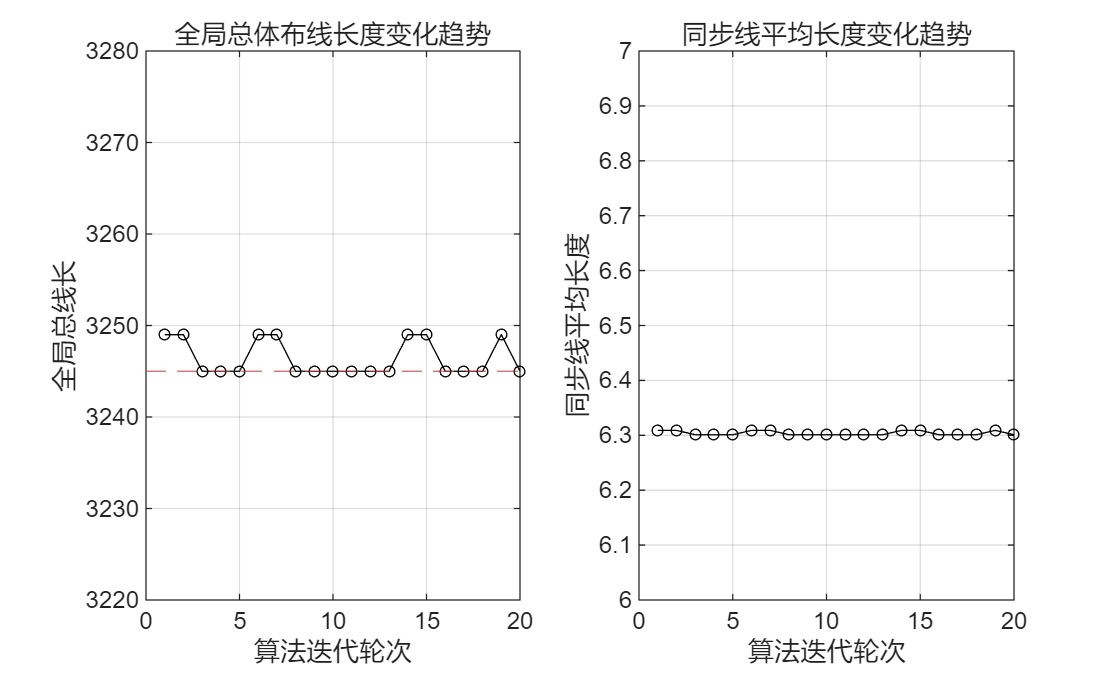

cycle = 1:1:20;
total_avg_length = [3249, 3249, 3245, 3245, 3245, 3249, 3249, 3245,3245,3245,3245,3245,3245,3249, 3249, 3245,3245,3245,3249, 3245];
sync_avg_length = [6.309, 6.309, 6.301, 6.301, 6.301, 6.309, 6.309, 6.301, 6.301, 6.301, 6.301, 6.301, 6.301, 6.309, 6.309, 6.301, 6.301, 6.301, 6.309, 6.301];
max_length = 15;
min_total_length = 3245;

% 总线长度趋势图
figure;
subplot(1, 2, 1);
plot(cycle, total_avg_length, 'k-o', 'MarkerSize',4);
yline(min_total_length, 'Color','r', "LineStyle", "--");
xlabel('算法迭代轮次');
ylabel('全局总线长');
title('全局总体布线长度变化趋势');
ylim([3220, 3280]);
grid on;

subplot(1, 2, 2);
plot(cycle, sync_avg_length, 'k-o', 'MarkerSize',4);
xlabel('算法迭代轮次');
ylabel('同步线平均长度');
title('同步线平均长度变化趋势');
ylim([6, 7]);
grid on;